clc;
clear all;

Data = dlmread("data/bld1c.xyzc"," ");

% 掐头去尾
Data(1,:) = [];
Data(:,1) = [];

% 按照面片分离
% 面片拟合
cnum= max(Data(:,5))+1;
%mian = cell(cnum,1);
color = ['r','g','b','y'];
figure();
m_point = cell(cnum,1);
M_grid = cell(cnum,1);
for i = 1:cnum
    ind = Data(:,5) == i-1;
    
    temp = Data(ind,:);
    x = temp(:,1)';
    y = temp(:,2)';
    z = temp(:,3)';
    m_point{i} = [x',y',z'];
    %mian{i} = least_square_method2(x,y,z);
    
    scatter3(x', y', z', color(i));
    
    planeData=m_point{i};
 
    % 协方差矩阵的SVD变换中，最小奇异值对应的奇异向量就是平面的方向
    xyz0=mean(planeData,1);
    centeredPlane=bsxfun(@minus,planeData,xyz0);
    [U,S,V]=svd(centeredPlane);
     
    a=V(1,3);
    b=V(2,3);
    c=V(3,3);
    d=-dot([a b c],xyz0);
     
    % 图形绘制
    xfit = min(x):0.1:max(x);
    yfit = min(y):0.1:max(y);
    [XFIT,YFIT]= meshgrid (xfit,yfit);
    ZFIT = -(d + a * XFIT + b * YFIT)/c;
    
%     mesh(XFIT,YFIT,ZFIT);

    hold on;
    
    M_grid{i} = [XFIT(:),YFIT(:),ZFIT(:)];
end

% figure;
% 
% for i = 1:cnum
%     x = M_grid{i}(:,1);
%     y = M_grid{i}(:,2);
%     z = M_grid{i}(:,3);
%     
%     scatter3(x', y', z', color(i));
%     hold on;
% end
% 
% figure;

% 获取交点,进而获取特征线
limit = 0.1;

% cps1 = get_cross_points(M_grid{2}, M_grid{3}, limit);
% [num1, ~] = size(cps1)
% for i = 1:num1
%     x = cps1(:,1);
%     y = cps1(:,2);
%     z = cps1(:,3);
%     
%     scatter3(x', y', z', color(1));
% end

% 初步计算交线，储存端点坐标和方向向量
D_points = [];
strt_points = [];
directions = [];

[Dmax, Dmin, direction] = get_inter_line(M_grid{2}, M_grid{3},m_point{2}, m_point{3}, limit);
D_points = [D_points;Dmax;Dmin];
strt_points = [strt_points;Dmax];
directions = [directions;direction'];

[Dmax, Dmin, direction] = get_inter_line(M_grid{1}, M_grid{3},m_point{1}, m_point{3}, limit);
D_points = [D_points;Dmax;Dmin];
strt_points = [strt_points;Dmax];
directions = [directions;direction'];

[Dmax, Dmin, direction] = get_inter_line(M_grid{1}, M_grid{2},m_point{1}, m_point{2}, limit);
D_points = [D_points;Dmax;Dmin];
strt_points = [strt_points;Dmax];
directions = [directions;direction'];

%求最近点
m = get_nearestpointofline(strt_points, directions);

m =           556491.560806963
          2845586.73861781
         -17.4121071442035


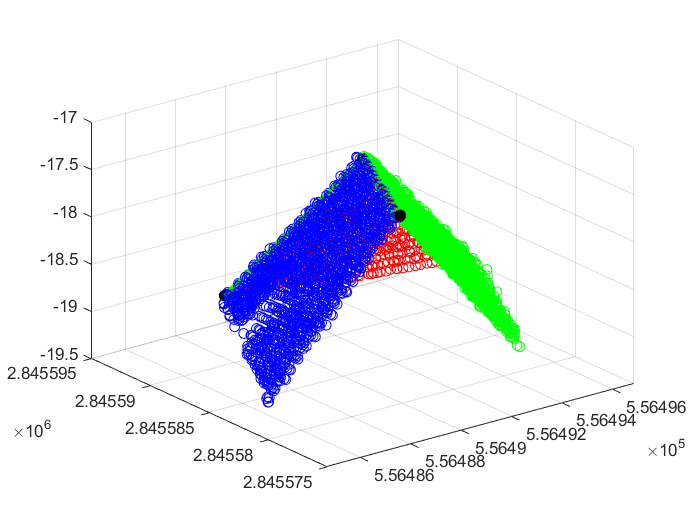

m = m';
scatter3(m(1),m(2),m(3),50,'black','filled');
hold on;

%提取其他端点并且重新生成特征线
endpoints = [m];
final_directions = [];
t=-1:0.1:1;
for p = 1:3
    po1 = D_points(2*p-1,:);
    po2 = D_points(2*p,:);
    
    % 剔除离交点近的点
    if norm(po1 - m) > norm(po2 - m)
        ep = po1;
        
    else
        ep = po2;
    end
    
    endpoints = [endpoints;ep];
    final_directions = [final_directions;ep-m];
    scatter3(ep(1),ep(2),ep(3),50,'black','filled');
    plot3([ep(1),m(1)],[ep(2),m(2)],[ep(3),m(3)],color(p),'LineWidth',3);
    hold on;
end


disp('四个端点的坐标：')

四个端点的坐标：


endpoints

endpoints =           556491.560806963          2845586.73861781         -17.4121071442035
          556489.239023396           2845578.5890564         -17.3772109797662
          556488.502113132          2845591.90598074         -18.9349713988165
          556496.826092188          2845589.63076647         -18.9601532911065


disp('屋脊线的方向向量')

屋脊线的方向向量


final_directions

final_directions =          -2.32178356742952         -8.14956140238792        0.0348961644372778
         -3.05869383108802          5.16736292792484         -1.52286425461306
          5.26528522488661          2.89214866189286         -1.54804614690301
